# Multi-way Interactions

This tutorial constructs hypergraphs from 2D and pairwise data using methods of multi-correlation. A multi-correlation is a function that measures the relationships between three or more variables. Based on the strength of these relationships between sets of variables, hyperedges may be defined and used to construct a hypergraph. This demo will walk through each of these steps using HAT [1].

## Multi-way Relationship Measures

Let $D\in\mathbf{R}^{n\times m}$ be a 2D data matrix with $m$ me1asurements taken on $n$ variables, and each variable represents a vertex in the hypergraph. Then the correlation matrix is defined$R = cor(D)\in \mathbf{R}^{n\times n}$. An individual entry $R_{i,j}$ is the *pairwise* relationship between the $i$th and $j$th random variables in $D\ldotp$ To determine the relationship between more than two variables, multi-correlation matrices examine minors or submatrices of $R$, which are denoted$R^{\prime }$. The below three measures are implemented in HAT.

### Drezner

In "Multirelation—a correlation among more than two variables," Zvi Drezner proposes a muli-correlation measure based on the linear fit of data [2]. Minors of$R$ are considered, and the linear fit between the random variables is determined according to the measure

$1-\lambda \left(R^{\prime } \right)$,

where $R^{\prime }$ denotes a minor of$R$ and$\lambda$ represents the smallest eigenvalue of the matrix.

### Wang and Zheng

In "Measures of correlation for multiple variables," Jianji Wang and Nanning Zheng define a multi-correlation measure according to the equation [3]:


$${\left(1-\det \left(R^{\prime } \right)\right)}^{0\ldotp 5}$$


### Taylor

In "A multi-way correlation coefficient," Benjamin Taylor defines a multi-correlation measure according to the equation [4]:


$$\frac{1}{\sqrt{k}}\mathrm{std}\left(\lambda_1 ,\ldots\ldotp \lambda_k \right)$$


where $k$ is the size of the minor $R^{\prime }$ and the values $\lambda_1,\dots,\lambda_k$ are the eigenvalues of $R^{\prime }$.

Each of the above 3 measures is implemented by HAT. In Example 1, the step-by-step process of computing the multi-way relationships is shown, and in Example 2, these methods are applied to construct a hypergraph from pairwise data using HAT.

## Example 1

This example walks through analyzing the minors of a correlation matrix. A small data matrix is given, all minors of size $3\times 3$ are extracted, and the multicorrelation functions are applied to each minor. This example doesn't use HAT but instead shows how HAT works. 

In this cell, a data matrix $D\in\mathbf{R}^{4\times 4}$ is created for a 4 variables with 4 measurements taken on each. The built-in MATLAB function corrcoef computes the correlation matrix $R = cor(D)\in \mathbf{R}^{4\times 4}$

% Set matrix D
D = [0.4218    0.6557    0.6787    0.6555
     0.9157    0.0357    0.7577    0.1712
     0.7922    0.8491    0.7431    0.7060
     0.9595    0.9340    0.3922    0.0318];
% Get correlation matrix R
R = corrcoef(D)

R =     1.0000   -0.1109   -0.3282   -0.7439
   -0.1109    1.0000   -0.5853    0.2351
   -0.3282   -0.5853    1.0000    0.6084
   -0.7439    0.2351    0.6084    1.0000


Extracting minors or submatrices of a matrix in MATLAB is as simple as taking the row and column slices of the original matrix. For the matrix $R$ above, the minor on variables 1, 2, and 3 is the submatrix:

% Manually get minor R(1,2,3)
R123 = [1.0000   -0.1109   -0.3282
        -0.1109    1.0000   -0.5853
        -0.3282   -0.5853    1.0000];
% Slices to get minor R(1,2,3)
R123 = R([1 2 3], [1 2 3])

R123 =     1.0000   -0.1109   -0.3282
   -0.1109    1.0000   -0.5853
   -0.3282   -0.5853    1.0000


To consider all possible $k-$way interactions among $n$ variables, the command nchoosek enumerates all possible indices that are used to extract minors of $R$. In the code below, all 3-way interactions are generated and listed as a row of the idxs matrix

n = 4;                  % Number of variables or nodes in D
k = 3;                  % Order of interactions (i.e. 3-way, 4-way, etc.)
idxs = nchoosek(1:n,k)  % List of all k-way interactions

idxs =      1     2
     1     3
     1     4
     2     3
     2     4
     3     4


To compute each multicorrelation measure for $k-$way interactions among $n$ variables, we can iterate over each set of indices used to extract minors of $R$. Then, for each minor, the multcorrelation is computed according to one of the measures given above [2,3,4].

type = 'Drezner';                           % TODO: Set which multi-correlation measure to use
for i=1:length(idxs)                        % Iterate over each k-minor of R
    minor = R(idxs(i,:), idxs(i,:));        % Extract the minor with column and row slices of R
    if strcmp(type,'Drezner')               
        disp(1 - min(eig(minor)));          % Drezner's equation
    elseif strcmp(type, 'Wang')
        disp((1-det(minor))^0.5);           % Wang and Zheng's equation
    elseif strcmp(type, 'Taylor')
        disp(w * std(eig(corrcoef(minor))));% Taylor's equation
    end
end

    0.1109

    0.3282

    0.7439

    0.5853

    0.2351

    0.6084



The process detailed in this example is automatically performed by HAT when the data matrix $D$ and order of the interactions $k$ is provided. Example 2 demonstrates perform these operations with HAT,

Create random data matrix

n = 4;
m = 4;
D = rand(n, m)

D =     0.6225    0.4709    0.2259    0.3111
    0.5870    0.2305    0.1707    0.9234
    0.2077    0.8443    0.2277    0.4302
    0.3012    0.1948    0.4357    0.1848


[mcr, vars] = HAT.multicorrelations(D, 3, 'Drezner')

mcr =     0.5386
    0.4353
    0.4110
    0.4528
    0.4279
    0.7381
    0.5404
    0.5551
    0.7145
    0.7067


vars =      1     2     3
     1     2     4
     1     2     5
     1     3     4
     1     3     5
     1     4     5
     2     3     4
     2     3     5
     2     4     5
     3     4     5


## Zach's Karate Club

In this example, multi-way correlation measures are utilized to identify high-order interactions in pairwise data. The Karate network is a social network of 34 individuals belonging to the same Karate club at a US university [5] and is canonical to network science. This data is built-in to HAT and can be accessed via the `HAT.load` method.

[A, ~] = HAT.load('karate');    % Load Karate adjacency matrix

The Karate network may be visualized as either an adjacency matrix or a pairwise graph

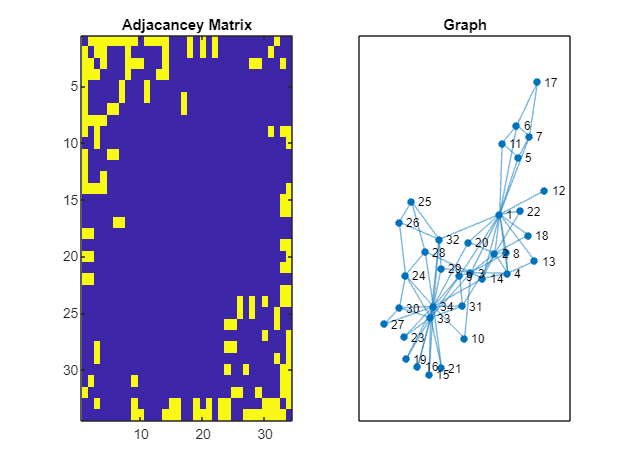

figure;
subplot(1,2,1); imagesc(A); title('Adjacancey Matrix');
subplot(1,2,2); plot(graph(A)); title('Graph');

To compute multi-way interactions with HAT, the data, order of the interaction and method (i.e. Drezner, Taylor, Wang) are passed to the method `HAT.multicorrelations. `The function then returns 2 vectors `[M, idxs]`, where `M` contains multi-way measurements and `idxs` contains the indices of `A` that correspond the the multicorrelation values in `M. `In this case, the pairwise adjacency matrix is utilized as the general 2D data matrix.

k = 3;
[M, idxs] = HAT.multicorrelations(A, k, 'Wang');

Given a set of multi-way measurements, the aim is to construct a hypergraph using HAT where high multi-correlations indicate the presence of a hyperedge. Below, the histogram of the multicorrelation scores is plotted.

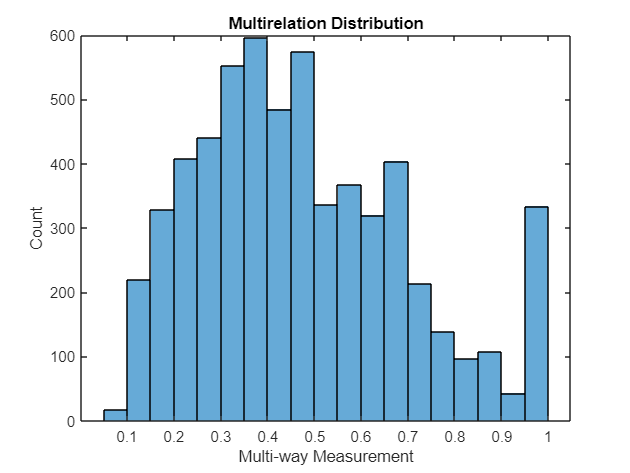

figure; histogram(M); title('Multirelation Distribution');
xlabel('Multi-way Measurement'); ylabel('Count');

There are several methods for determining which multicorrelations should represent a hyperedge. The simplest method is to set a minimum threshold `thresh` such that all multicorrelations in `M` that are greater than `thresh` indicate the presence of a hyperedge. Additional methods of setting a threshold for the multicorrelation to indicate a hyperedge could exploite hypergraph properties such as adding edges with the highest multi-correlation until the hypergraph is fully connected, achieves a certain density, or has another desiarable property.

In this cell, a threshold `thresh` is set as the median value of `M` and the set of indices with multicorrelations larger than `thresh` are extracted from the `idxs` variable.

t = mean(M) + std(M);       % Set thershold
m = find(M > t);            % Find idxs in M with value > thresh
hyperedges = idxs(m, :);    % Sets of vertices with measures > thresh are extracted

Given the set of hyperedges, these must be transformed to an incidence matrix in order to construct a hypergraph. This is done with the function below

IM = HAT.hyperedge2IM(hyperedges);

Given the incidence matrix a hypergraph representation of the Karate network may finally be constructed.

HG = Hypergraph('IM', IM)

HG =   Hypergraph with properties:

             IM: [34×930 double]
    edgeWeights: [930×1 double]
    nodeWeights: [34×1 double]


## References

[1] Joshua Pickard, Can Chen, Rahmy Salman, Cooper Stansbury, Sion Kim, Amit Surana, and Indika Rajapakse. "Hypergraph Analysis Toolbox for Chromosome Conformation."

[2] Zvi Drezner. Multirelation—a correlation among more than two variables. Computational Statistics & Data Analysis, 19(3):283–292, 1995.

[3] Jianji Wang and Nanning Zheng. Measures of correlation for multiple variables. arXiv preprint arXiv:1401.4827, 2014.

[4] Benjamin M Taylor. A multi-way correlation coefficient. arXiv preprint arXiv:2003.02561, 2020.

[5] W. W. Zachary, An information flow model for conflict and fission in small groups, Journal of Anthropological Research 33, 452-473 (1977)